Получаем DataSet

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path);
z = y(:,1);
NOTES = 88;
data = reshape(z,4*Fs,[]); %????????? ?????????? ?????? ?? 88 ???, ???????? ?????? 176400?88
NFFT = 1024;
N = 86; %????????????, ??? ????? ????? ?????? 100 ?????????????? ????? ??? ?????????? 100*1024 ???????, ???? ?????? ???? ?????? 
for num_notes = 1 : NOTES
    notes = reshape(data(1:NFFT*N,num_notes),NFFT,N); % ?????????? 100*1024 ??????? ? ????? ??????????????? ? ?????? 1024?100
    notes = abs(fft(notes)); %?????????????? ????? ?? ??????? ?????
    DataSet(:,:,num_notes) = notes(1:512,:);
    mean_pdf(:,num_notes) = mean(notes(1:512,:),2); %???????????? ?????????????? ???????? ??????? ?? ??????????? ???????
    std_pdf(:,num_notes) = std(notes(1:512,:),1,2);   % Maybe we must set 0 for secod parameter ???????????? ????????? ??????? ?? ??????????? ???????
end

save('DataSet.mat', 'DataSet')

Не рабочий Байесовский встроенній Классификатор

clear all
close all
load DataSetOld.mat
X = reshape(DataSet,200,[])';
for k=1:88
    Y(:,k) = repmat({dec2hex(k)},100,1);
end
Y = reshape(Y,[],1);
cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);
XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);
Mdl = fitcnb(XTrain,YTrain);
label = predict(Mdl,XTest);
table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2640×2 table
    TrueLabel    PredictedLabel
    _________    ______________

      {'1'}          {'1' }    
      {'1'}          {'3' }    
      {'1'}          {'10'}    
      {'1'}          {'1' }    
      {'1'}          {'1' }    
      {'1'}          {'7' }    
      {'1'}          {'7' }    
      {'1'}          {'1' }    
      {'1'}          {'5' }    
      {'1'}          {'1' }    
      {'1'}          {'3' }    
      {'1'}          {'7' }    
      {'1'}          {'1' }    
      {'1'}          {'1' }    
      {'1'}          {'7' }    
      {'1'}          {'1' }    


13.05.2021

clear all
close all
load DataSet

X = reshape(DataSet,512,[])';

for k=1:88
    Y(:,k) = repmat(k,86,1);
end
Y = reshape(Y,[],1);
cv = cvpartition(Y,'HoldOut',0.3);

trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

Mdl = fitcnb(XTrain,YTrain);
label = predict(Mdl,XTest);

table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2270×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        1              28      
        1               7      
        1               9      
        1               8      
        1               9      
        1               8      
        1               7      
        1               8      
        1               8      
        1               5      
        1               8      
        1               9      
        1              33      
        1               9      
        1              33      
        1               9      


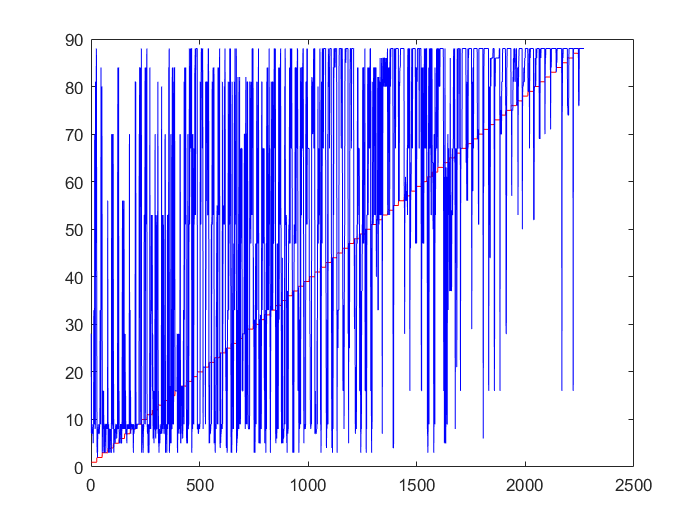


plot(YTest,'r')
hold on
plot(label,'b')
hold off

Тот же скрипт, только с моей датой для обучения и теста

clear all
close all
load('data.mat')

% X = reshape(DataSet,512,[])';

% for k=1:88
%     Y(:,k) = repmat(k,86,1);
% end
% Y = reshape(Y,[],1);
cv = cvpartition(Y,'HoldOut',0.3);

trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

Mdl = fitcnb(XTrain,YTrain);
label = predict(Mdl,XTest);

table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2270×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       
        1              1       


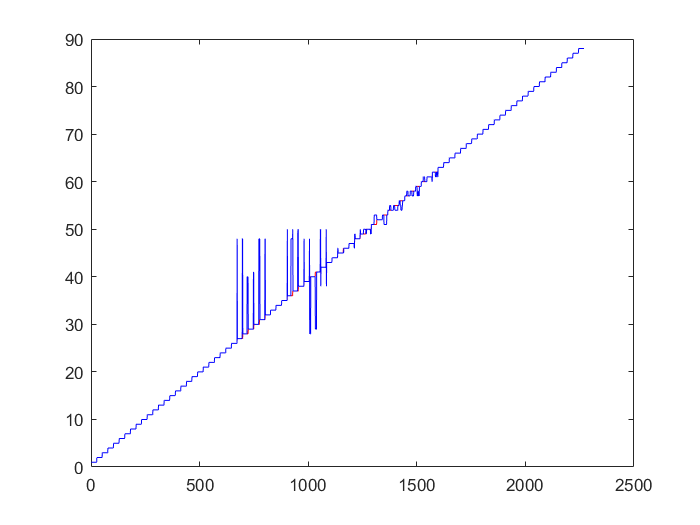


plot(YTest,'r')
hold on
plot(label,'b')
hold off